clc
clear
%%%% SCARA_T3-401S %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

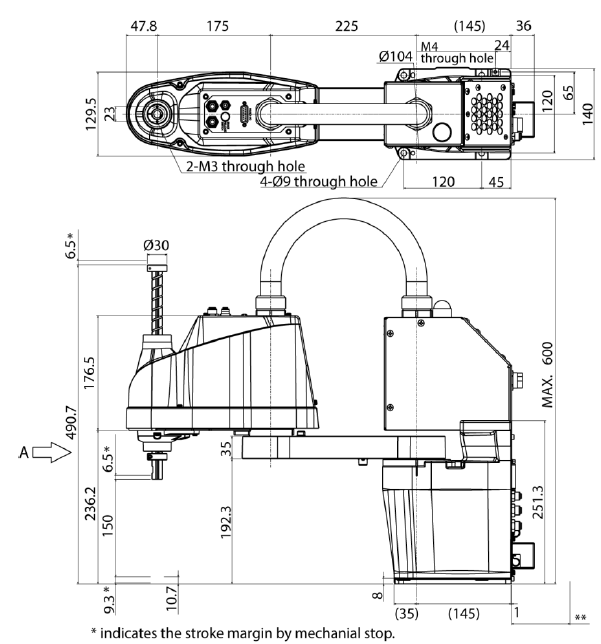

%%%% Cinemática_Directa %%%%%%%%%%%%%%%%%

L1 = 225;
L2 = 175;

theta1 = input('Ingrese valor de theta1: ')

theta1 = 15.3180

theta2 = input('Ingrese valor de theta2: ')

theta2 = 11.5020

d3 = input('Ingrese valor de d3 (Negativo): ')

d3 = -20.0010

theta4 = input('Ingrese valor de theta4: ')

theta4 = 25.9360


theta1 = deg2rad(theta1);
theta2 = deg2rad(theta2);
theta4 = deg2rad(theta4);

M01 = DHL(theta1,0,L1,0);
M12 = DHL(theta2,0,L2,0);
M23 = DHL(0,d3,0,0);
M34 = DHL(theta4,0,0,0);

M04 = M01*M12*M23*M34;

Euler = tform2eul(M04);
Euler_z = rad2deg(Euler(1,1));


%%% Cinemática_Inversa %%%%%%%%%%%%%%%%

px = M04(1,4);
py = M04(2,4);
pz = M04(3,4);

%%% Theta_2 %%%%%%%%%%%%%

d = sqrt(px^2 + py^2);
D2 = (d^2 - L1^2 - L2^2)/(2*L1*L2);
S2p = sqrt(1 - D2^2);
S2n = -sqrt(1 - D2^2);

theta_2p = atan2(S2p,D2);
theta_2p = rad2deg(theta_2p);

theta_2n = atan2d(S2n,D2);

%%% Theta_1 %%%%%%%%%%%%%%

beta = atan2(py,px);
Da = (L1^2 + d^2 - L2^2)/(2*L1*d);
Sap = sqrt(1 - Da^2);
San = -sqrt(1 - Da^2);
alphap = atan2(Sap,Da);
alphan = atan2(San,Da);

theta_1p = rad2deg(beta - alphap);
theta_1n = rad2deg(beta - alphan);

%%% d3 %%%%%%%%%%%%%%%%%%%

d3 = pz;

%%% Theta_4 %%%%%%%%%%%%%%%%%%%%%%%
syms theta44

M344 = DHL(theta44,0,0,0)

$$M344 = \left(\begin{array}{cccc} \cos\left(\theta_{44}\right) & -\sin\left(\theta_{44}\right) & 0 & 0\\ \sin\left(\theta_{44}\right) & \cos\left(\theta_{44}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


R03 = M01(1:3,1:3)*M12(1:3,1:3)*M23(1:3,1:3);
% th4 = R03'*M04(1:3,1:3)
th4 = R03'*(rotz(Euler_z))

th4 =     0.8993   -0.4374         0
    0.4374    0.8993         0
         0         0    1.0000


theta_4 = atan2d(th4(2,1),th4(1,1));

%%%%% Resultados %%%%%%%%%%%%%%%%%%%%

theta_11p = theta_1p

theta_11p = 15.3180

theta_11n = theta_1n

theta_11n = 25.3775

theta_22p = theta_2p

theta_22p = 11.5020

theta_22n = theta_2n

theta_22n = -11.5020

d_3 = d3

d_3 = -20.0010

theta_44 = theta_4

theta_44 = 25.9360